% Histogramas y dist. estadistica de las mediciones
% Parámetros de estad. descrp. 
%Cargar datos
%data = [7 2 4 8 7 2 9 6 4 2 1 3 7 2 1 3 5 1 6];    (poner aquí sus datos)
data = xlsread('Actividad3_mediciones');
%estadística descriptiva
media = mean(data);
mediana = median(data);
desvest = std(data);
varz = var(data);
moda = unique(data); H=histc(data,moda); moda = moda(H==max(H)); %cuantas modas tienes?
if length(moda)>1
fprintf('\n Media = %.2f',media)
fprintf('\n Mediana = %.2f',mediana)
fprintf('\n Moda = %.2f %.2f %.2f', moda)
fprintf('\n Desviación estándar = %.2f',desvest)
fprintf('\n Varianza = %.2f\n',varz)
else
est_descr = [media, mediana, moda, desvest, varz]; %este es un vector de 5 valores que incluye media, ...)
array2table(est_descr, 'VariableNames', {'Media', 'Mediana',... %LA estadistica descriptiva va de arreglo a tabla
'Moda', 'Desviación estándar', 'Varianza'})
end

ans = 1×5 table
    Media     Mediana    Moda    Desviación estándar    Varianza
    ______    _______    ____    ___________________    ________

    81.638      80        82           18.263            333.53 


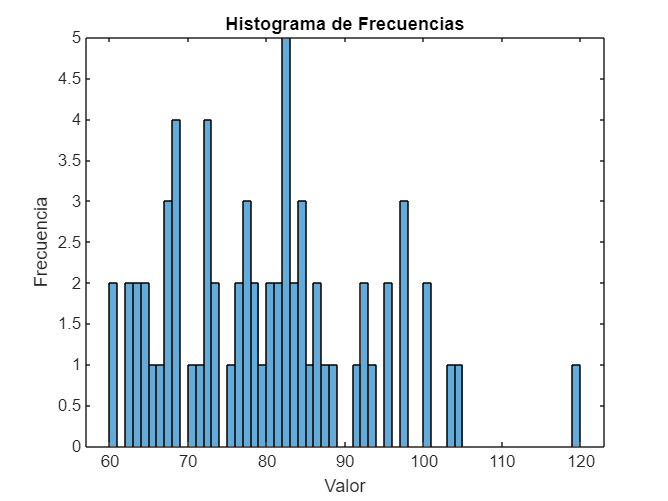

%histograma
histogram(data, [60:1:120])
title("Histograma de Frecuencias")
xlabel("Valor")
ylabel("Frecuencia")

%tabla de frecuencias
tab = tabulate(data);% Esta funcion tabula todos tus valores pero incluye desde 1 hasta tu valor maximo
min_tab = find(tab==min(data));%encuentra la posición del punto minimo en la variable tab.
array2table(tab(min_tab:end,:),'VariableNames',{'Valor','Frecuencia absoluta',...
'Frecuencia relativa (%)'})

ans = 125×3 table
    Valor    Frecuencia absoluta    Frecuencia relativa (%)
    _____    ___________________    _______________________

     60               2                     2.8986         
     61               0                          0         
     62               2                     2.8986         
     63               2                     2.8986         
     64               2                     2.8986         
     65               1                     1.4493         
     66               1                     1.4493         
     67               3                     4.3478         
     68               4                     5.7971         
     69               0                          0         
     70               1                     1.4493         
     71               1                     1.4493         
     72               4                